# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

clear all;
robotNames = [
    "kinovaGen3";            % 1
    "universalUR3";          % 2
    "universalUR5";          % 3
    "universalUR10";         % 4
    "frankaEmikaPanda";      % 5
    "kukaIiwa7";             % 6
    "rethinkSawyer";         % 7
    "abbIrb120";             % 8
];

endEffectors = [
    "EndEffector_Link";      % 1 kinova
    "tool0";                 % 2 UR3
    "tool0";                 % 3 UR5
    "tool0";                 % 4 UR10
    "panda_hand";            % 5 Franka 
    "iiwa_link_7";           % 6 iiwa7 
    "right_hand";            % 7 sawyer 
    "tool0";                 % 8 abbIrb120
];
%% ✅ 选择机械臂
id =5;  % ← 修改这里来选择机器人 (1=Gen3, 2=UR5, 3=UR10)

robot_name = robotNames(id);
endEffector = endEffectors(id);
robot = loadrobot(robot_name, 'DataFormat','column');


for b = 1:numel(robot.Bodies)
    if ~strcmp(robot.Bodies{b}.Joint.Type,'fixed')
        disp(robot.Bodies{b}.Joint.Name)
    end
end

panda_joint1
panda_joint2
panda_joint3
panda_joint4
panda_joint5
panda_joint6
panda_joint7
panda_finger_joint1
panda_finger_joint2




%% 验证
q = homeConfiguration(robot);
T_ee = getTransform(robot, q, endEffector);

fprintf("Selected Robot : %s\n", robot_name);

Selected Robot : frankaEmikaPanda


%% ✅ 获取关节数量
numJoints = numel(homeConfiguration(robot));

%% ✅ 输出
fprintf("Selected Robot: %s\n", robot_name);

Selected Robot: frankaEmikaPanda


fprintf("End Effector: %s\n", endEffector);

End Effector: panda_hand


fprintf("Number of joints: %d\n", numJoints);

Number of joints: 9


Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

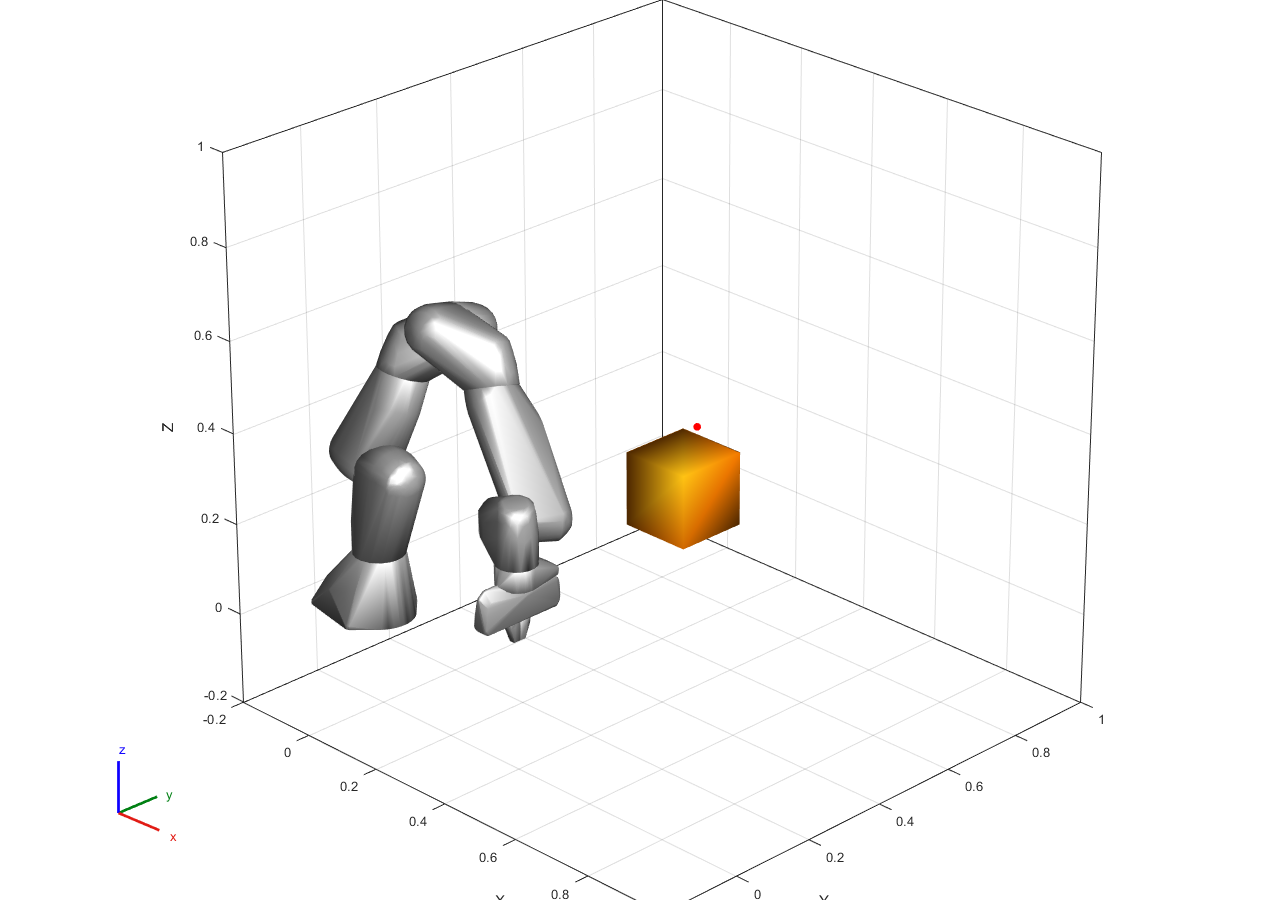

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;
% ==== 放大并规范 3D 视图 ====
fig = gcf; set(fig,'Color','w','Position',[100 100 1280 900]);  % 放大窗口
ax  = gca; view(ax, 45, 25); grid(ax,'on'); box(ax,'on'); hold(ax,'on');
axis(ax,'vis3d'); daspect(ax,[1 1 1]); pbaspect(ax,[1 1 1]);   % 立方比例


xlim(ax,[-0.2, 1]);
ylim(ax,[-0.2, 1]);
zlim(ax,[-0.2, 1]);

camlight(ax,'headlight'); lighting(ax,'gouraud');  % 柔和光照

drawnow;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.05; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

历时 1.120525 秒。


Qtheta = 9.2940e+04

RAR = 2.8039

历时 1.039173 秒。


Qtheta = 8.2869e+04

RAR = 2.8025

历时 1.055991 秒。


Qtheta = 7.6433e+04

RAR = 2.8009

历时 1.036848 秒。


Qtheta = 6.7520e+04

RAR = 2.8013

历时 1.032835 秒。


Qtheta = 4.2364e+04

RAR = 2.8017

历时 1.029983 秒。


Qtheta = 3.9482e+04

RAR = 2.8019

历时 1.029923 秒。


Qtheta = 3.0351e+04

RAR = 2.8028

历时 1.040479 秒。


Qtheta = 2.7760e+04

RAR = 2.8017

历时 1.026388 秒。


Qtheta = 2.2804e+04

RAR = 2.8015

历时 1.027427 秒。


Qtheta = 2.0317e+04

RAR = 2.8021

历时 1.032950 秒。


Qtheta = 1.6045e+04

RAR = 2.8008

历时 1.025373 秒。


Qtheta = 1.4335e+04

RAR = 2.8001

历时 1.025533 秒。


Qtheta = 1.3410e+04

RAR = 2.7997

历时 1.068503 秒。


Qtheta = 1.3122e+04

RAR = 2.7990

历时 1.045997 秒。


Qtheta = 1.2880e+04

RAR = 2.7991

历时 1.060427 秒。


Qtheta = 1.2954e+04

RAR = 2.7990

历时 1.070125 秒。


Qtheta = 1.2593e+04

RAR = 2.7981

历时 1.022944 秒。


Qtheta = 1.2524e+04

RAR = 2.7986

历时 1.026820 秒。


Qtheta = 1.2376e+04

RAR = 2.7981

历时 1.028409 秒。


Qtheta = 1.2277e+04

RAR = 2.7981

历时 1.023557 秒。


Qtheta = 1.1830e+04

RAR = 2.7972

历时 1.026142 秒。


Qtheta = 1.0542e+04

RAR = 2.7973

历时 1.021719 秒。


Qtheta = 1.0447e+04

RAR = 2.7975

历时 1.025994 秒。


Qtheta = 8.6424e+03

RAR = 2.7976

历时 1.031651 秒。


Qtheta = 8.8243e+03

RAR = 2.7976

历时 1.023800 秒。


Qtheta = 8.6376e+03

RAR = 2.7975

历时 1.059611 秒。


Qtheta = 8.6886e+03

RAR = 2.7968

历时 1.102151 秒。


Qtheta = 8.8355e+03

RAR = 2.7967

历时 1.063696 秒。


Qtheta = 8.8663e+03

RAR = 2.7969

历时 1.023862 秒。


Qtheta = 8.6125e+03

RAR = 2.7972

历时 1.028369 秒。


Qtheta = 8.4167e+03

RAR = 2.7967

历时 1.016612 秒。


Qtheta = 8.1603e+03

RAR = 2.7972

历时 1.035831 秒。


Qtheta = 8.2040e+03

RAR = 2.7977

历时 1.015667 秒。


Qtheta = 7.4364e+03

RAR = 2.7979

历时 1.017953 秒。


Qtheta = 7.3973e+03

RAR = 2.7974

历时 1.016546 秒。


Qtheta = 7.4225e+03

RAR = 2.7971

历时 1.018918 秒。


Qtheta = 7.9273e+03

RAR = 2.7971

历时 1.015466 秒。


Qtheta = 7.7495e+03

RAR = 2.7968

历时 1.021561 秒。


Qtheta = 7.7432e+03

RAR = 2.7971

历时 1.014407 秒。


Qtheta = 7.6669e+03

RAR = 2.7972

历时 1.017802 秒。


Qtheta = 7.7030e+03

RAR = 2.7976

历时 1.016811 秒。


Qtheta = 7.7789e+03

RAR = 2.7979

历时 1.013171 秒。


Qtheta = 7.8807e+03

RAR = 2.7975

历时 1.020957 秒。


Qtheta = 8.1639e+03

RAR = 2.7977

历时 1.020383 秒。


Qtheta = 8.1487e+03

RAR = 2.7976

历时 1.030750 秒。


Qtheta = 8.1695e+03

RAR = 2.7974

历时 1.023445 秒。


Qtheta = 8.1443e+03

RAR = 2.7976

历时 1.020252 秒。


Qtheta = 7.9812e+03

RAR = 2.7975

历时 1.013656 秒。


Qtheta = 7.6916e+03

RAR = 2.7973

历时 1.012428 秒。


Qtheta = 7.8846e+03

RAR = 2.7971

历时 1.013700 秒。


Qtheta = 7.8316e+03

RAR = 2.7973

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   1


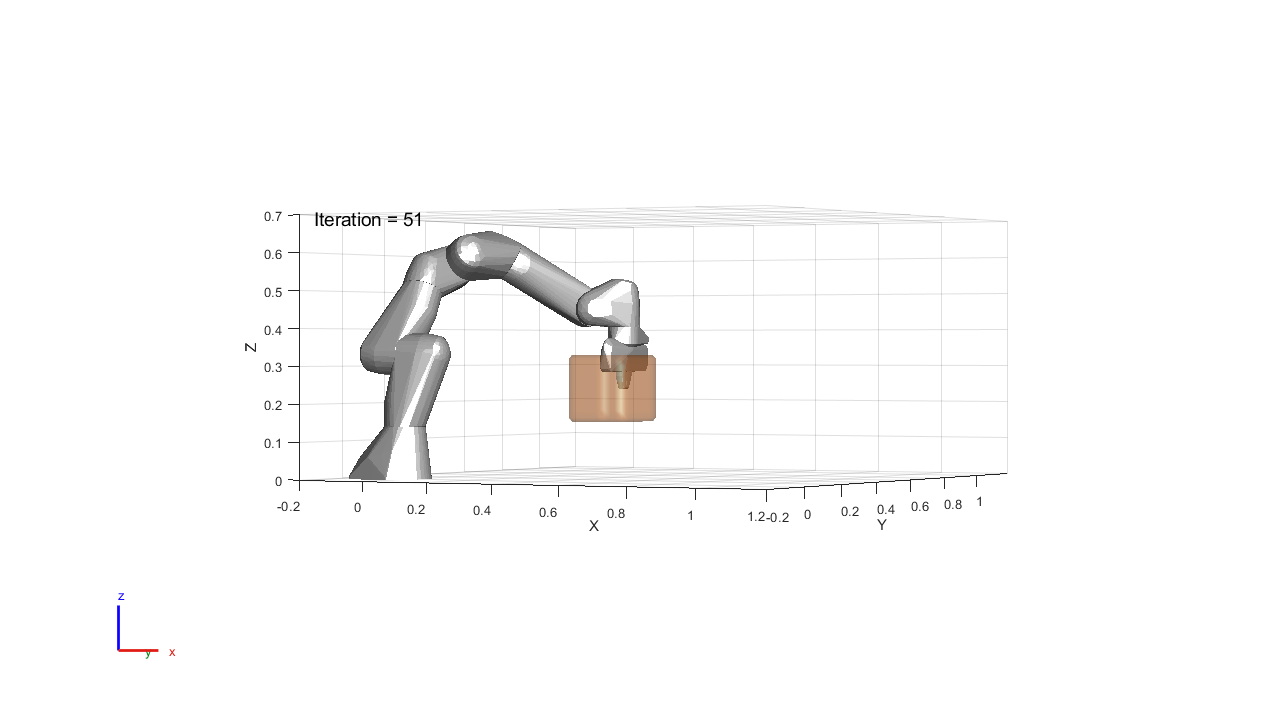

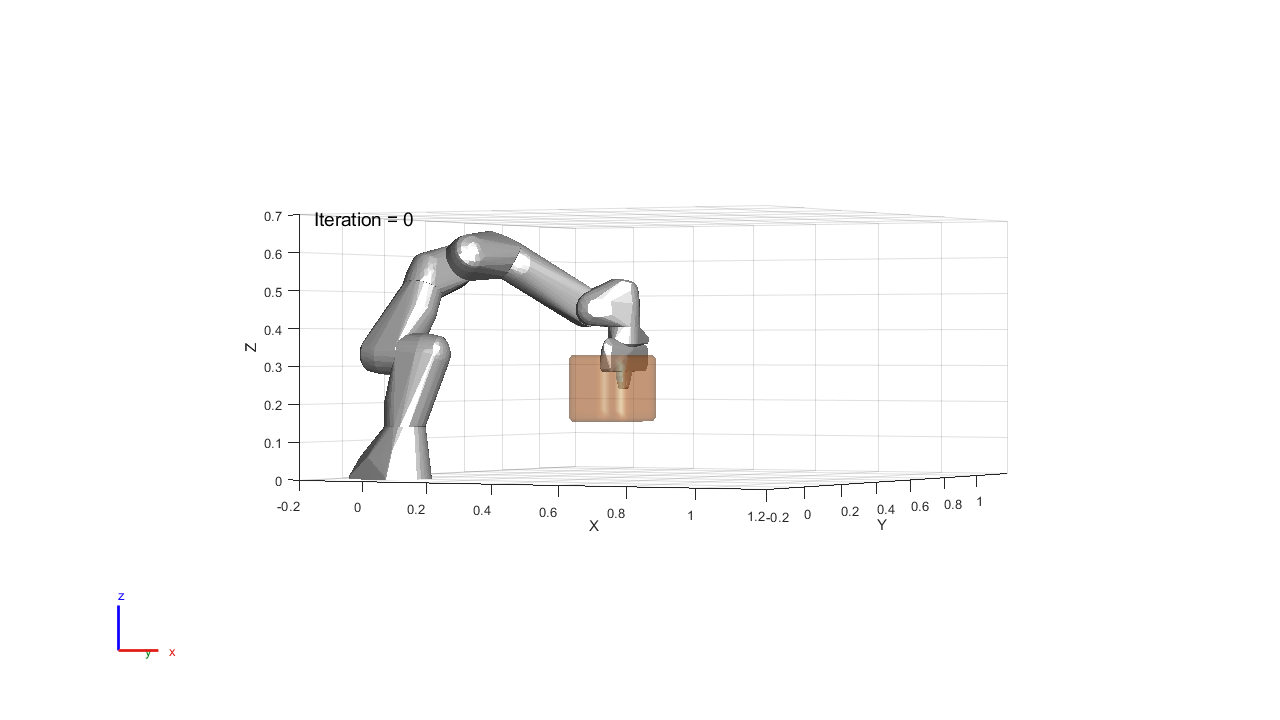

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.